%"Dispatcher" by Kambadur Ananthamurthy
% This code uses actual dfbf curves from my data and analyses it for time
% cells using multiple methods
% Currently this is being tested for single session data. I will test with a
% batch, soon.

tic
clear
close all

## Addpaths


addpath(genpath('/Users/ananth/Documents/MATLAB/CustomFunctions')) % my custom functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis')) % Additional functions
addpath(genpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis/Suite2P-ananth'))
addpath('/Users/ananth/Documents/MATLAB/ImagingAnalysis/Suite2P-ananth/localCopies')


## Dataset

make_db
ops0.fig                       = 1;
ops0.saveData                  = 1;
ops0.onlyProbeTrials           = 0;
ops0.loadSyntheticData         = 1;
ops0.doSigOnly                 = 0;

if ops0.loadSyntheticData
    setupSyntheticDataParameters
end

## Figure details

if ops0.fig
    figureDetails = compileFigureDetails(20, 2, 10, 0.5, 'jet'); %(fontSize, lineWidth, markerSize, transparency, colorMap)
end

## Main script

fprintf('Analyzing %s_%i_%i - Date: %s\n', db.mouseName, ...
    db.sessionType, ...
    db.session, ...
    db.date)

Analyzing M26_5_4 - Date: 20180514


saveDirec = '/Users/ananth/Desktop/Work/Analysis/Imaging/';
saveFolder = [saveDirec db.mouseName '/' db.date '/'];

%for i = 1:length(sdcp)
%i = 1;
i = length(sdcp);
if ops0.loadSyntheticData
    load([saveFolder ...
        'synthDATA' ...
        '-' num2str(i) ...
        '_tCP' num2str(sdcp(i).timeCellPercent) ...
        '_cO' lower(sdcp(i).cellOrder) ...
        '_mHTP' num2str(sdcp(i).maxHitTrialPercent) ...
        '_hTPA' lower(sdcp(i).hitTrialPercentAssignment) ...
        '_tO' lower(sdcp(i).trialOrder) ...
        '_eW' num2str(sdcp(i).eventWidth{1}) ...
        '_eAF' sdcp(i).eventAmplificationFactor ...
        '_eT' lower(sdcp(i).eventTiming) ...
        '_sF' num2str(sdcp(i).startFrame) ...
        '_eF' num2str(sdcp(i).endFrame) ...
        '_iFWHM' num2str(sdcp(i).imprecisionFWHM) ...
        '_iT' lower(sdcp(i).imprecisionType) ...
        '_n' lower(sdcp(i).noise) ...
        '_np' num2str(sdcp(i).noisePercent) ...
        '_batch', ...
        '.mat']);
    myData.dfbf = sdo.syntheticDATA;
    myData.dfbf_2D = sdo.syntheticDATA_2D;
    myData.baselines = zeros(size(sdo.syntheticDATA)); %initialization
else
    %Load processed data (processed dfbf for dataset/session)
    myData = load([saveFolder db.mouseName '_' db.date '.mat']);
end
trialDetails = getTrialDetails(db);

Getting trial details ...
... done!



%Significant-Only Traces
if ops0.doSigOnly
    if ops0.onlyProbeTrials
        disp('Only analysing Probe Trials ...')
        dfbf_sigOnly = findSigOnly(myData.dfbf(:, iProbeTrials, :));
    else
        dfbf_sigOnly = findSigOnly(myData.dfbf);
    end
    DATA = dfbf_sigOnly;
else
    DATA = myData.dfbf;
end

## Analysis Pipeline: Method A - Mehrab's Reliability Analysis (Bhalla Lab)

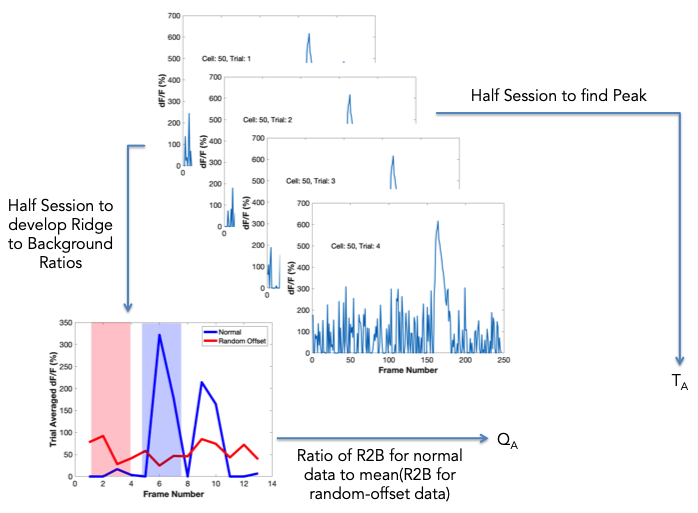

mAInput.cellList = 1:1:size(DATA,1); %using all cells
mAInput.onFrame = sdcp.startFrame;
mAInput.offFrame = sdcp.endFrame;
mAInput.ridgeHalfWidth = 100; %in ms
mAInput.nIterations = 5000; %number of iterations of randomisation used to find averaged r-shifted rb ratio - might have to go as high as 3000.
mAInput.selectNonOverlappingTrials = 1; %1 - non-overlapping trial sets used for kernel estimation and rb ratio calculation, 0 - all trials used for both
mAInput.earlyOnly = 0; %0 - uses all trials; 1 - uses only the first 5 trials of the session
mAInput.startTrial = 1; %the analysis begins with this trial number (e.g. - 1: analysis on all trials)

[mAOutput] = runMehrabR2BAnalysis(DATA, mAInput, trialDetails);

Now calculating Ridge to Background Ratios ...
... 10 cells examined ...
... 20 cells examined ...
... 30 cells examined ...
... 40 cells examined ...
... 50 cells examined ...
... 60 cells examined ...
... 70 cells examined ...
... 80 cells examined ...
... 90 cells examined ...
... 100 cells examined ...
... 110 cells examined ...
... 120 cells examined ...
... 130 cells examined ...


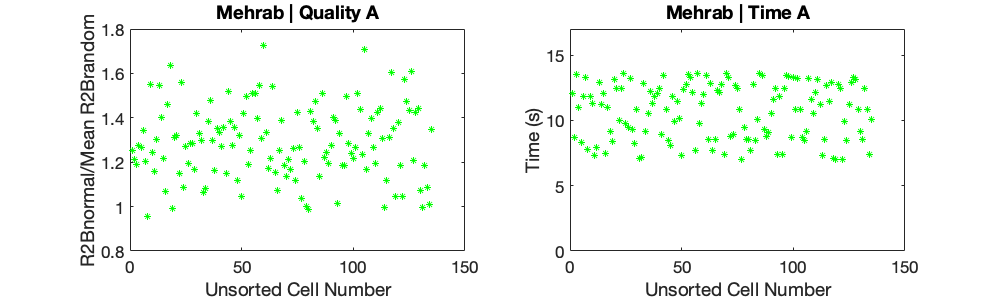

save([saveFolder db.mouseName '_' db.date '_methodA.mat' ], 'mAInput', 'mAOutput')
fig1 = figure(1);
set(fig1,'Position',[300,300,1000,300])
clf
subplot(1, 2, 1)
plot(mAOutput.Q, 'g*')
title('Mehrab | Quality A', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
ylabel('R2Bnormal/Mean R2Brandom', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(1, 2, 2)
plot(mAOutput.T/db.samplingRate, 'g*')
ylim([0 (db.nFrames/db.samplingRate)])
%ylim([(mAInput.onFrame-10)/db.samplingRate (mAInput.offFrame + 10)/db.samplingRate])
title('Mehrab | Time A', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
ylabel('Time (s)', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

if ops0.loadSyntheticData
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodA_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
        '-djpeg');
else
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodA_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
        '-djpeg');
end

## Analysis Pipeline: Method B - William Mau's Temporal Information (Eichenbaum Lab)

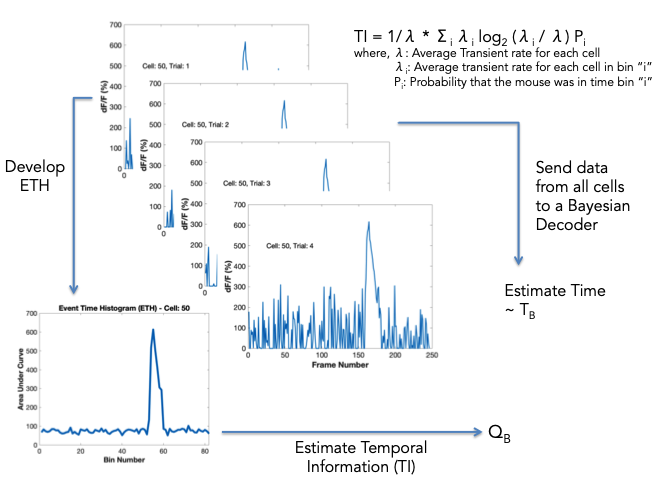

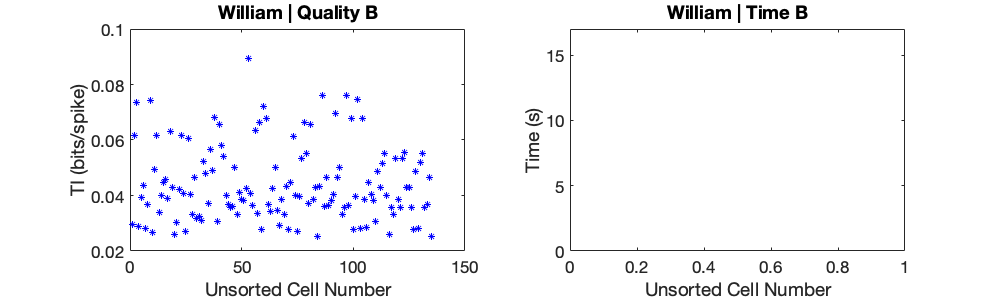

mBInput.delta = 3;
[mBOutput] = runWilliamTIAnalysis(DATA);
save([saveFolder db.mouseName '_' db.date '_methodB.mat' ], 'mBInput', 'mBOutput')
fig2 = figure(2);
set(fig2,'Position',[300,300,1000,300])
clf
subplot(1, 2, 1)
plot(mBOutput.Q, 'b*')
title('William | Quality B' , ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
ylabel('TI (bits/spike)', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(1, 2, 2)
plot((mBOutput.T * mBInput.delta)/db.samplingRate, 'b*')
ylim([0 (db.nFrames/db.samplingRate)])
title('William | Time B', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
ylabel('Time (s)', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

if ops0.loadSyntheticData
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodB_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
        '-djpeg');
else
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodB_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
        '-djpeg');
end

## Analysis Pipeline: Method C - Simple Analysis

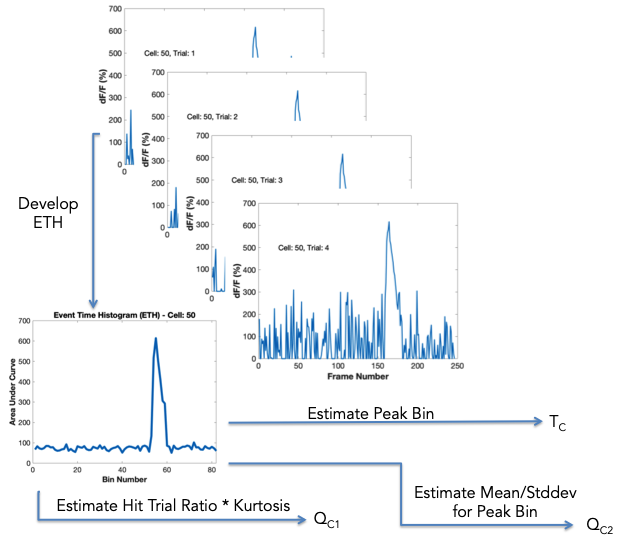

mCInput.delta = 3;
mCInput.skipFrames = [];
mCInput.trialThreshold = 25; % in %
[mCOutput] = runSimpleTCAnalysis(DATA, mCInput);

Now, developing ETH for 135 cells ...
... 10 cells analysed ...
... 20 cells analysed ...
... 30 cells analysed ...
... 40 cells analysed ...
... 50 cells analysed ...
... 60 cells analysed ...
... 70 cells analysed ...
... 80 cells analysed ...
... 90 cells analysed ...
... 100 cells analysed ...
... 110 cells analysed ...
... 120 cells analysed ...
... 130 cells analysed ...
... done!


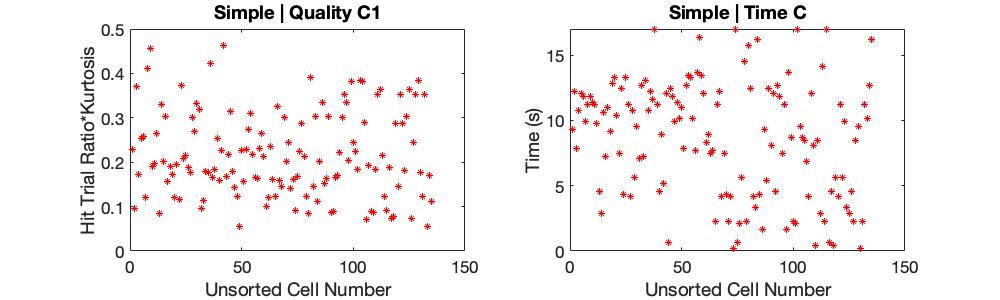

save([saveFolder db.mouseName '_' db.date '_methodC.mat' ], 'mCInput', 'mCOutput')
fig3 = figure(3);
set(fig3,'Position',[300,300,1000,300])
clf
subplot(1, 2, 1)
plot(mCOutput.Q1, 'r*')
title('Simple | Quality C1' , ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
ylabel('Hit Trial Ratio*Kurtosis', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(1, 2, 2)
plot((mCOutput.T * mCInput.delta)/db.samplingRate, 'r*')
ylim([0 (db.nFrames/db.samplingRate)])
title('Simple | Time C', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
ylabel('Time (s)', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

if ops0.loadSyntheticData
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodC1_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
        '-djpeg');
else
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodC1_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
        '-djpeg');
end

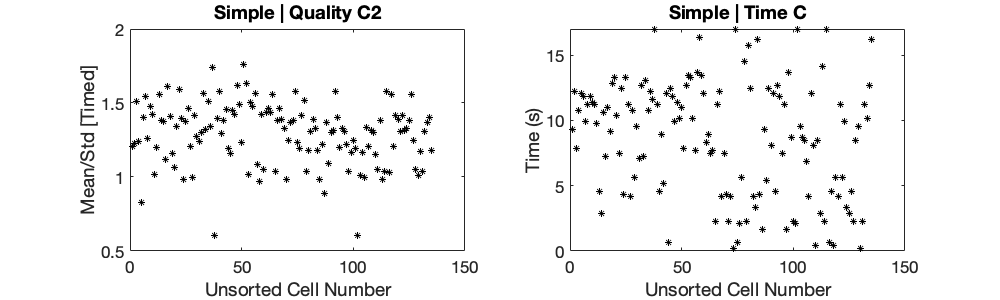


fig4 = figure(4);
set(fig4,'Position',[300,300,1000,300])
clf
subplot(1, 2, 1)
plot(mCOutput.Q2, 'k*')
%ylim([0 10])
title('Simple | Quality C2' , ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
ylabel('Mean/Std [Timed]', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(1, 2, 2)
plot((mCOutput.T * mCInput.delta)/db.samplingRate, 'k*')
ylim([0 (db.nFrames/db.samplingRate)])
title('Simple | Time C', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Unsorted Cell Number', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
ylabel('Time (s)', ...
    'FontSize', figureDetails.fontSize,...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

if ops0.loadSyntheticData
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodC2_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
        '-djpeg');
else
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_methodC2_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
        '-djpeg');
end

## Second Order Stats to compare the outputs

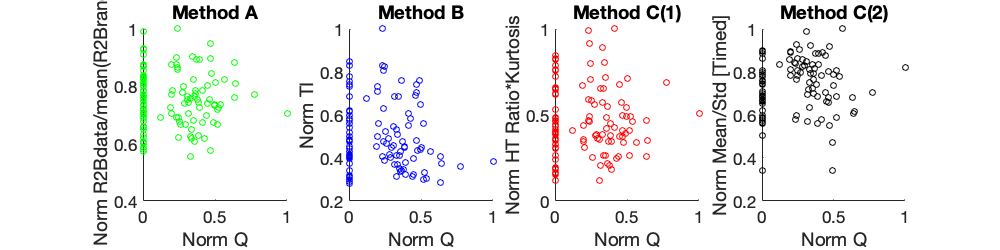

%Normalize the "reliability" vectors ignoring "Inf"
sdo.Q_norm = (sdo.Q) ./max(sdo.Q);
mAOutput.Q_norm = (mAOutput.Q) ./max(mAOutput.Q(~isinf(mAOutput.Q)));
mBOutput.Q_norm = (mBOutput.Q) ./max(mBOutput.Q);
mCOutput.Q1_norm = (mCOutput.Q1) ./max(mCOutput.Q1);
mCOutput.Q2_norm = (mCOutput.Q2) ./max(mCOutput.Q2);

fig5 = figure(5);
set(fig5,'Position',[300,300,1000,250])
clf
subplot(1, 4, 1)
scatter(sdo.Q_norm, mAOutput.Q_norm, 'g');
title('Method A', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Norm Q', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Norm R2Bdata/mean(R2Brand)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(1, 4, 2)
scatter(sdo.Q_norm, mBOutput.Q_norm, 'b');
title('Method B', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Norm Q', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Norm TI', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(1, 4, 3)
scatter(sdo.Q_norm, mCOutput.Q1_norm, 'r');
title('Method C(1)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Norm Q', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Norm HT Ratio*Kurtosis', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(1, 4, 4)
scatter(sdo.Q_norm, mCOutput.Q2_norm, 'k');
title('Method C(2)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Norm Q', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Norm Mean/Std [Timed]', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

if ops0.loadSyntheticData
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_normQScatter_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
        '-djpeg');
else
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_normQScatter_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
        '-djpeg');
end

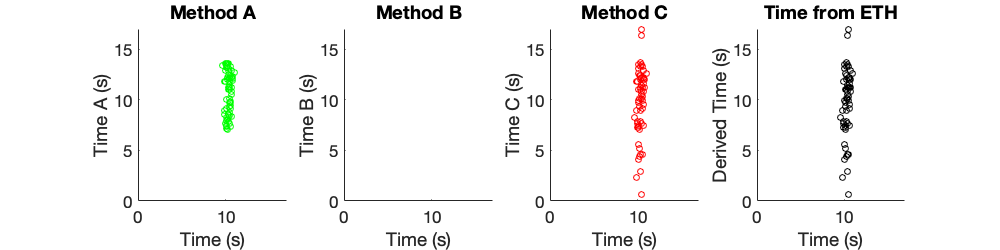


fig6 = figure(6);
set(fig6,'Position',[300,300,1000,250])
clf
subplot(1, 4, 1)
scatter(nanmean(sdo.frameIndex, 2)/db.samplingRate, mAOutput.T/db.samplingRate, 'g');
xlim([0 (db.nFrames/db.samplingRate)])
ylim([0 (db.nFrames/db.samplingRate)])
title('Method A', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Time (s)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Time A (s)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(1, 4, 2)
scatter(nanmean(sdo.frameIndex, 2)/db.samplingRate, (mBOutput.T * mCInput.delta)/db.samplingRate, 'b');
xlim([0 (db.nFrames/db.samplingRate)])
ylim([0 (db.nFrames/db.samplingRate)])
title('Method B', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Time (s)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Time B (s)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(1, 4, 3)
scatter(nanmean(sdo.frameIndex, 2)/db.samplingRate, (mCOutput.T * mCInput.delta)/db.samplingRate, 'r');
xlim([0 (db.nFrames/db.samplingRate)])
ylim([0 (db.nFrames/db.samplingRate)])
title('Method C', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Time (s)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Time C (s)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

subplot(1, 4, 4)
scatter(nanmean(sdo.frameIndex, 2)/db.samplingRate, (sdo.T * mCInput.delta)/db.samplingRate, 'k');
xlim([0 (db.nFrames/db.samplingRate)])
ylim([0 (db.nFrames/db.samplingRate)])
title('Time from ETH', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
xlabel('Time (s)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
ylabel('Derived Time (s)', ...
    'FontSize', figureDetails.fontSize, ...
    'FontWeight', 'bold')
set(gca,'FontSize', figureDetails.fontSize-3)

if ops0.loadSyntheticData
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_TScatter_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session) '_synthData'],...
        '-djpeg');
else
    print(['/Users/ananth/Desktop/figs/multipleTCA/multipleTCA_TScatter_' ...
        db.mouseName '_' num2str(db.sessionType) '_' num2str(db.session)],...
        '-djpeg');
end

toc

Elapsed time is 443.612985 seconds.


disp('All done!')

All done!
